# Electrode localization using FreeSurfer + iElectrodes

Written by Qian Chu (Max Planck - University of Toronto Centre)

Contact: qian.chu@{mail.utoronto.ca, ae.mpg.de, nyu.edu}

Version: 20230816

FreeSurfer version tested: 7.4.1

iElectrodes version tested: 1.020

## Checklist

Make sure that you have:

- Acquired the pre-op T1-weighted MRI scan (hereafter referred to as T1) in DICOM (.dcm) or NIFTI (.nii) format

- Acquired the post-op CT scan (hereafter referred to as CT)

- [Optional] Acquired the pre-op T2-weighted MRI scan (hereafter referred to as T2)

- FreeSurfer installed on this computer. FreeSurfer can be installed on Linux or MacOS. Download instructions: [https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads.](https://surfer.nmr.mgh.harvard.edu/fswiki/rel7downloads.) It is also recommended you set up automatic sourcing so that FreeSurfer commands are immediately available after opening a terminal. For instructions see [https://surfer.nmr.mgh.harvard.edu/fswiki/SetupConfiguration_Linux](https://surfer.nmr.mgh.harvard.edu/fswiki/SetupConfiguration_Linux)

- Downloaded iElectrodes from [https://sourceforge.net/projects/ielectrodes/files/latest/download](https://sourceforge.net/projects/ielectrodes/files/latest/download) and put the unzipped package in this elec_loc folder.

## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

config.dir_fs = '/home/ieegneuron2brain/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

config.dir_fs_subjects = '/home/ieegneuron2brain/Desktop/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

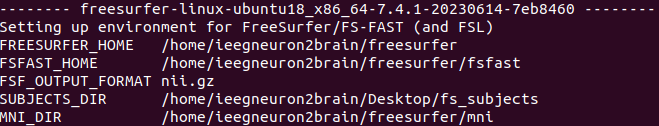

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
elec_loc_dir        = strjoin(elec_loc_path_parts(1:end-1), filesep);

% Set up path
cd(elec_loc_dir)

iel_info = dir('iElectrodes*');
if isempty(iel_info)
    error('No iElectrodes package detected. Please download iElectrods from\n%s\nAnd move the unzipped file to %s', ...
        'https://sourceforge.net/projects/ielectrodes/files/latest/download', elec_loc_dir)
end

addpath(genpath(iel_info.name))
addpath(genpath('functions'))
addpath('external')

% Sanity if FreeSurfer directory is valid
fs_sanity_check(config)

## Convert DICOM to NIFTI if not done already

[https://www.mathworks.com/matlabcentral/fileexchange/42997-xiangruili-dicm2nii](https://www.mathworks.com/matlabcentral/fileexchange/42997-xiangruili-dicm2nii)

Usually the raw brain scans (MRI & CT) are in DICOM (a folder of a series of .dcm files, one slice per file) format. For the convenience of processing, they need to be converted to a single NIFTI (.nii) file. **Make sure that .dcm files in one folder all belong to the same scan (i.e., dedicated T1/T2/CT folders).**

Run this section multiple times to convert T1/T2/CT scans.

### Input

- [Select from GUI] Patient brain scan T1/T2/CT folder containing .dcm files

### Output

- A .nii file in the same folder

scan_dir = uigetdir('', 'Select the folder containing DICOM files of the brain scan');
dicm2nii(scan_dir, scan_dir, '.nii')

## [Optional] De-identify the MRI scan

[https://surfer.nmr.mgh.harvard.edu/fswiki/MiDeFace](https://surfer.nmr.mgh.harvard.edu/fswiki/MiDeFace)

MRI scan inevitably covers the face which makes it possible to reconize the patient's identity. De-facing is recommended for the sake of patient privacy should the scan be shared (e.g., for open data purposes). The FreeSurfer MiDeFace function performs a minimal modification of face voxels to achieve de-identification. The constrained yet sufficient de-facing process would ideally introduce very little influence on subsequent analyses, e.g. co-registration with CT.

De-facing takes ~10 minutes.

### Input

- [Select from GUI] T1 scan

### Output

- De-faced T1 scan with suffix "_deface" in the same directory

### Post-execution behavior

- Freeview visualization of the de-faced scan as an isosurface for qualify check. The isosurface may take some moments to load.

- Adjust threshold on the bottom left if needed to visualize the whole face

- 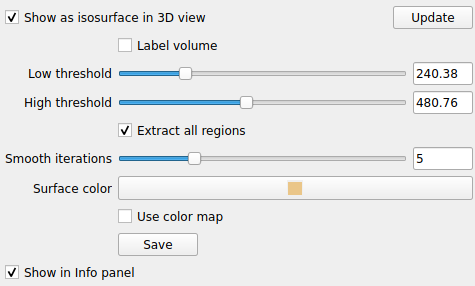

- If de-facing is satisfactory (identity unrecognizable), close Freeview to proceed

mideface(config)

## [Optional] Align T1 scan to AC-PC line

This program relies on the FreeSurfer full reconstruction pipieline known as "recon-all". The input for recon-all is the T1 scan, preferrably aligned to AC-PC line. If you would like to do this pre-recon alignment, you can easily do so in Freeview, the visualization tool in FreeSurfer.

- Open Freeview by typing "freeview" in your terminal or by running the code below

- File > Load Volume, select the T1 scan

- Tools > Transform Volume

- Use the "Rotate" and "Translate" tools to align

- Use "Save Volume as" button to save the transformed scan

Code for selecting a T1 scan and opening it in Freeview:

[t1_ali_name, t1_ali_dir] = uigetfile({'*.nii; *.nii.gz; *.mgz'}, ...
    'Select T1 scan');
t1_ali_path = fullfile(t1_ali_dir, t1_ali_name);

bash_code = sprintf('%s; freeview -v %s', ...
    fs_setup_code(config), t1_ali_path);

system(bash_code);

## Run FreeSurfer recon-all if not done already

[https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all](https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all)

"recon-all" is a command line script in FreeSurfer. The name comes from "reconstruction of all structures," and this command calls a series of scripts for preprocessing, segmentation, and cortical surface reconstruction.

### Inputs

- [Type in field below] Patient ID

- [Select from GUI] Patient T1 scan (could be de-faced and/or aligned to AC-PC though both are optional)

### Outputs

- FreeSurfer subject folder *$SUBJECTS_DIR/PATIENT_NAME*

After executing, wait a few minutes to make sure recon-all initiates without errors. The execution takes **10 hours or more **so it might be a good idea to run it overnight. Lay down .... ;)

pat.name = "TWH";
pat.dir  = fullfile(config.dir_fs_subjects, pat.name);

[t1_recon_name, t1_recon_dir] = uigetfile({'*.nii; *.nii.gz; *.mgz'}, ...
    'Select T1 scan');
t1_recon_path = fullfile(t1_recon_dir, t1_recon_name);

bash_code = sprintf('%s; recon-all -s %s -i %s -all', ...
    fs_setup_code(config), pat.name, t1_recon_path);

system(bash_code);

## [If you have run recon-all before] Select FreeSurfer subject folder

If you have run recon-all outside of this script, simply tell it where the output folder is. The script automatically takes the selected folder name as patient name.

pat_dir_filter = config.dir_fs_subjects;

pat.dir = uigetdir(pat_dir_filter, 'Select patient folder in FreeSurfer subjects directory');
pat_dir_parts = split(pat.dir, filesep);
pat.name = pat_dir_parts{end};

% Check if recon-all was complete using DKT atlas file
if ~exist(fullfile(pat.dir, 'mri', 'aparc.DKTatlas+aseg.mgz'), 'file')
    error(['%s is not a valid FreeSurfer subject directory (aparc.DKTatlas+aseg.mgz not found)\n' ...
        'Please make sure you have run FreeSurfer recon-all beforehand\n' ...
        'See more at https://surfer.nmr.mgh.harvard.edu/fswiki/recon-all'], pat_dir)
end
fprintf('Patient %s selected', pat.name)

## Import CT to subject folder

From now on we will utilize the FreeSurfer subject folder (*$SUBJECTS_DIR/PATIENT_NAME*) to store files for this script.

### Input

- [Select from GUI] CT scan

### Output

- Imported CT scan at *ct/postop_ct.nii*

import_ct(config, pat)

## [Optional] Import T2 to subject folder

The T2 scan is not used anywhere in this script, but some people may need it for other purposes (e.g., subfield segmentation) so let's include it in the folder.

### Input

- [Select from GUI] T2 scan

### Output

- Imported T2 scan at *t2/t2.nii*

import_t2(config, pat)

## Convert .mgz to .nii

Some FreeSurfer .mgz output files are used by iElectrodes, yet iElectrodes only recognizes NIFTI (.nii). The function below does a stacked conversion.

### Inputs

- [Auto-loaded] .mgz files in "mri" subfolder

### Outputs

- ..nii files in "mri" subfolder

mgz2nii(config, pat)

## Co-register CT to T1 MRI

### Inputs

- [Select from dropdown box] Co-registration method ("freesurfer" or "spm")

- [Auto-loaded] CT scan at *ct/postop_ct.nii*

- [Auto-loaded] T1 scan at *mri/orig.nii*

### Output

If using FreeSurfer's mri_coreg ([https://surfer.nmr.mgh.harvard.edu/fswiki/mri_coreg](https://surfer.nmr.mgh.harvard.edu/fswiki/mri_coreg)):

- CT aligned to T1 space: *ct/postop_ct_coreg_fs.nii*

- Transformation matrix: *ct/ct2t1.lta*

If using SPM's spm_coreg ([https://github.com/spm/spm12/blob/master/spm_coreg.m](https://github.com/spm/spm12/blob/master/spm_coreg.m)):

- CT aligned to T1 space: *ct/postop_ct_coreg_spm.nii*

- Transformation matrix: *ct/ct2t1.mat*

### Post-execution behavior

- Freeview visualization of the co-registered CT on top of the T1 scan

- Check how well the skull imaged by T1 (usually dark) and CT (high-intensity) agree on each other. You can uncheck the "post_op_ct_coreg_*" layer to view exclusively T1

- If co-registration is satisfactory, close Freeview to proceed

- If not, a manual co-registration might be needed. To do so, transform CT using Freeview tools described in the [Optional] Align T1 scan to AC-PC line section. For instructions see step 3 of [https://www.protocols.io/view/modular-reconstruction-and-co-registration-of-imag-5qpvornedv4o/v2?step=3.](https://www.protocols.io/view/modular-reconstruction-and-co-registration-of-imag-5qpvornedv4o/v2?step=3.)

method = "freesurfer";
t1_ct_coreg(config, pat, method)

## Electrode labeling using iElectrodes

In this pipeline we use [iElectrodes](https://sourceforge.net/p/ielectrodes/wiki/Home/), an easy-to-use and robust toolbox for localizing intracranial electrodes. The code in this section creates a new subfolder to store localization outputs (*iel*) and launches iElectrodes

iel_dir = fullfile(pat.dir, 'iel');
if ~exist(iel_dir, 'dir'), mkdir(iel_dir), end
cd(pat.dir)
electrodes_gui

### iElectrodes toolbars

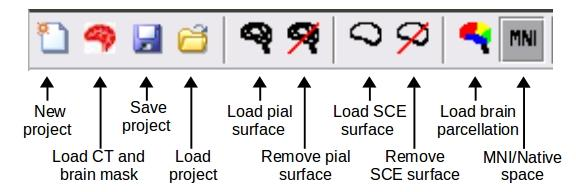

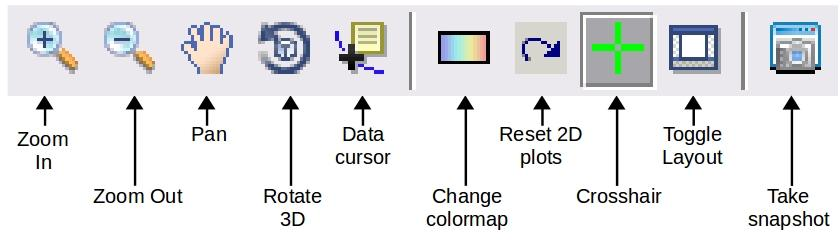

### Steps

- Click "New project" (see icon above) and load *mri/orig.nii.* T1 scan will appear on the top right corner of the iElectrodes window once loading is complete

- Click "Load CT and brain mask" (see icon above). You will be prompted to select the CT scan at *ct/postop_ct_coreg_<method>.nii*. After a while, you will be prompted again to select the brain mask. You can load the co-registered CT again. Using other masks like ribbon.nii might make it hard to visualize other landmarks like bolts, which are sometimes useful when navigating electrode locations.

- Follow [this tutorial](https://sourceforge.net/p/ielectrodes/wiki/Localization%20and%20labeling%20of%20intracranial%20electrodes/) to threshold CT, select above-threshold voxels, cluster and label electrodes.

- You can always save your progress at any stage by clicking "Save project" (see icon above). The saved .iel file should contain all the necessary components to retrieve your progress.

- After you are done, click 'Save/Export Electrodes' (see icon below) to save the electrode outputs in various forms. For generating the label tables in later steps, select the second output option to generate a plain txt file with channel name and XYZ coordinates in the native T1 space. It is recommended that you save it as *iel/PATIENT_NAME_elec.txt* (e.g., TWH001_elec.txt)

 

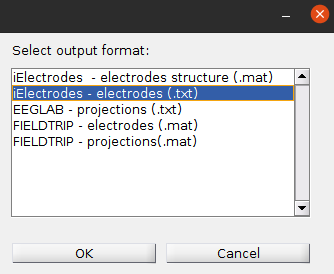

## [If using Behke-Fried depth electrodes] Estimate microwire location

iElectrodes cannot properly recognize microwires (which may or may not be visible on a post-op CT). A workaround is to estimate their location using locations of the 1st and 2nd electrodes (deepest two) and the distance between the first electrode and the microwire bundle.

### Input

- [Select from GUI] Electrode location .txt file

- [Type in field below] Known distance from the microwire bundle to the deepest macro contact (specify in code below)

### Output

- New electrode location .txt file with suffix "_u" in the same folder

% Specify distance from the microwire bundle to the deepest macro contact
% (in mm)
micro_to_macro_dist = 3.75;

% Select the electrode output .txt file
estimate_micro(pat, micro_to_macro_dist)

## Get FreeSurfer labels in the native space

Since recon-all also produces brain segmentation and parcellation, we can automatically read the label value for each electrode from <aparc.***.mgz> files and find the corresponding label from *$FREESURFER_HOME/FreeSurferColorLUT.txt*. For details of the parcellations see [https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation](https://surfer.nmr.mgh.harvard.edu/fswiki/CorticalParcellation)

### Input

- [Select from GUI] Electrode location .txt file (can be the output of microwire position estimation)

### Output

- Electrode location table (in native space) at *iel/PATIENT_NAME_elec_native.csv*

label_native(config, pat)

## Get electrode coordinates in MNI305 and MNI152 space [PENDING FREESURFER COMMUNITY REVIEW]

For group-level visualization of electrode location, mapping locations from native to standardized spaces is usually helpful. This section does two linear transforms to electrode locations to map them to:

- MNI305, also known as the fsaverage space. FreeSurfer automatically co-registers the native T1 onto this space and stores the native-to-MNI305 transformation matrix at *mri/transforms/talairach.xfm.*

- MNI152 space. The MNI305-to-MNI152 matrix is provided in [https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems](https://surfer.nmr.mgh.harvard.edu/fswiki/CoordinateSystems).

In addition to generating location tables just like in the previous section, the code also automatically generates .node files. These are useful for visualizing electrode locations in some other softwares (e.g., BrainNet Viewer, Surf Ice). Below is an example visualization of *_elec_mni305.node on top of rh.curv in Surf Ice:

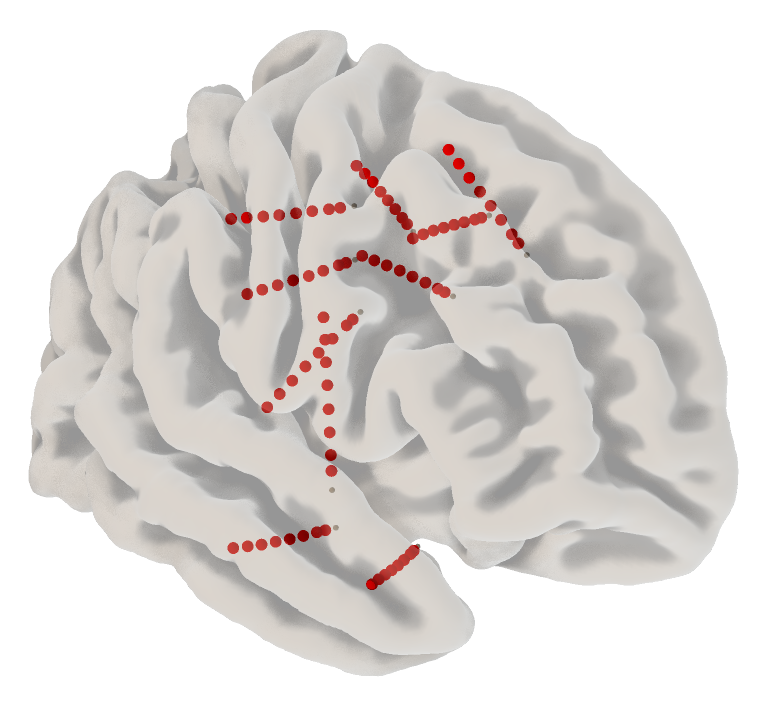

### Input

- [Select from GUI] Electrode location .txt file (can be the output of microwire position estimation)

### Output

- Electrode location table (in MNI305/fsaverage) at *iel/PATIENT_NAME_elec_mni305.csv*

- Electrode location node file (in MNI305/fsaverage) at *iel/PATIENT_NAME_elec_mni305.node*

- Electrode location table (in MNI152) at *iel/PATIENT_NAME_elec_mni152.csv*

- Electrode location node file (in MNI152) at *iel/PATIENT_NAME_elec_mni152.node*

label_mni(pat)